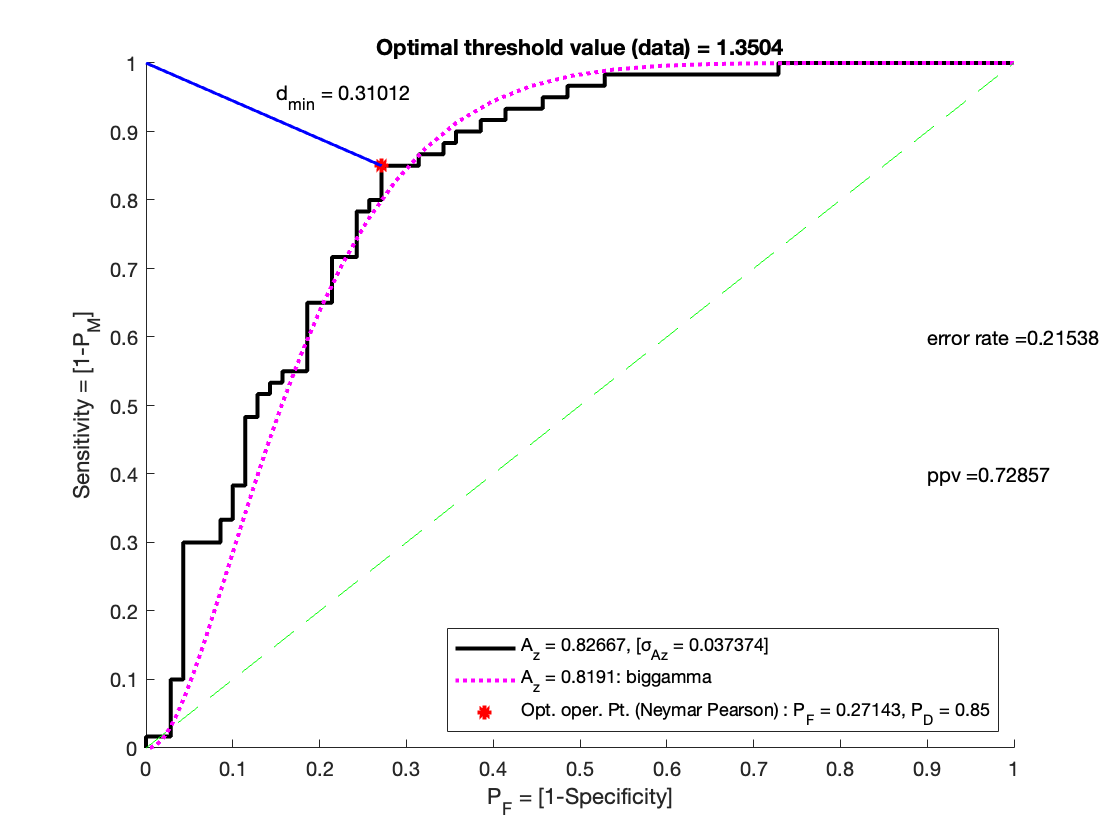


clear;clc;

file = 'Douglas-proj.xls';
nsmooth=8;
Data = xlsread(file);
Absent = (Data(1:70));
Present = (Data(71:end));
fit_x = linspace(0,10,130);
sorted = sortrows(Data, 1, 'descend');



% ROC Curve
N0=length(Absent);
N1=length(Present);
dat=[Absent;Present];
resp=[zeros(N0,1);ones(N1,1)];
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,dat,1);
AOC = calculateROCarea(resp,dat); % Area under ROC Curve
A1 = AOC/(2-AOC);
A2 = 2 * AOC^2/(1+AOC);
STDdeviation = sqrt((AOC*(1-AOC) + (N1-1)*(A1-AOC^2) + (N0-1)*(A2-AOC^2))/(N0*N1));



% Normal Distribution

parNormal_0 = fitdist(Absent,'Normal');
pdfNormal_0 = pdf('Normal',fit_x,parNormal_0.mu,parNormal_0.sigma);
cdfNormal_0 = cdf('Normal',fit_x,parNormal_0.mu,parNormal_0.sigma);

parNormal_1 = fitdist(Present,'Normal');
pdfNormal_1 = pdf('Normal',fit_x,parNormal_1.mu,parNormal_1.sigma);
cdfNormal_1 = cdf('Normal',fit_x,parNormal_1.mu,parNormal_1.sigma);

PF_Normal = 1-cdfNormal_0;
PD_Normal = 1-cdfNormal_1;

resp_Normal = [zeros(length(PF_Normal),1);ones(length(PD_Normal), 1)];
dat_Normal = [PF_Normal';PD_Normal'];
AOC_Normal = calculateROCarea(resp_Normal, dat_Normal);
dist_n = zeros(130,1);
 for i = 1:130
     dist_n(i, 1) = pdist([0,1;PF_Normal(i), PD_Normal(i)],'euclidean'); 
 end
 [opt_dist_n, I_n] = min(dist_n);
sorted_n = sortrows(dat_Normal, 1, 'descend');

% Gamma Distribution

parGamma_0 = fitdist(Absent,'Gamma');
pdfGamma_0 = pdf('Gamma',fit_x,parGamma_0.a,parGamma_0.b);
cdfGamma_0 = cdf('Gamma',fit_x,parGamma_0.a,parGamma_0.b);

parGamma_1 = fitdist(Present,'Gamma');
pdfGamma_1 = pdf('Gamma',fit_x,parGamma_1.a,parGamma_1.b);
cdfGamma_1 = cdf('Gamma',fit_x,parGamma_1.a,parGamma_1.b);

PF_Gamma = 1-cdfGamma_0;
PD_Gamma = 1-cdfGamma_1;

resp_Gamma = [zeros(length(PF_Gamma),1);ones(length(PD_Gamma), 1)];
dat_Gamma = [PF_Gamma';PD_Gamma'];
AOC_Gamma = polyarea(PF_Gamma, PD_Gamma)+0.5;
dist_g = zeros(130,1);
 for i = 1:130
     dist_g(i, 1) = pdist([0,1;PF_Gamma(i), PD_Gamma(i)],'euclidean'); 
 end
 [opt_dist_g, I_g] = min(dist_g);
 sorted_g = sortrows(dat_Gamma, 1, 'descend');

dist = zeros(130,1);
 for i = 1:130
     dist(i, 1) = pdist([0,1;pf(i), pd(i)],'euclidean'); 
 end
 [opt_dist, I] = min(dist);
vtOpt = sorted(I);
figure
hold on
title(['Optimal threshold value (data) = ', num2str(vtOpt)])
xlabel("P_F = [1-Specificity]")
ylabel("Sensitivity = [1-P_M]")
plot(pf,pd, 'k', 'LineWidth', 2) % black line
%plot(PF_Normal,PD_Normal, 'b--') % Blue dashed
plot(PF_Gamma,PD_Gamma, 'm:', "linewidth", 2) % Magenta dotted
plot(pf(I), pd(I), 'r*', "linewidth", 2) % optimal threshold
plot([0 pf(I)], [1 pd(I)], 'b-', 'LineWidth', 1.5) % blue line
plot(0:1,0:1, "g--", 'HandleVisibility','off') % green dashed line
text(0.15,0.95,['d_m_i_n = ',num2str(opt_dist)])
% text(.7,.4,'d_m_i_n (intersection) = 0.337')
% text(.7,.3,'d_m_i_n (midpoint) = 0.349')
PPV = 51/70;
err_rate = 28/130;
text(.9,.6,['error rate =',num2str(err_rate)])
text(.9,.4,['ppv =',num2str(PPV)])

legend(['A_z = ', num2str(AOC) , ', [σ_A_z = ' , num2str(STDdeviation), ']'], ...
    ['A_z = ', num2str(AOC_Gamma), ': biggamma'], ...
    [ 'Opt. oper. Pt. (Neymar Pearson) : P_F = ',  num2str((pf(I))), ', P_D = ', num2str(pd(I))] , ...
      'Location', 'Southeast')
% ["std = ", num2str(STDdeviation)] need to add standard deviation into legend
hold off

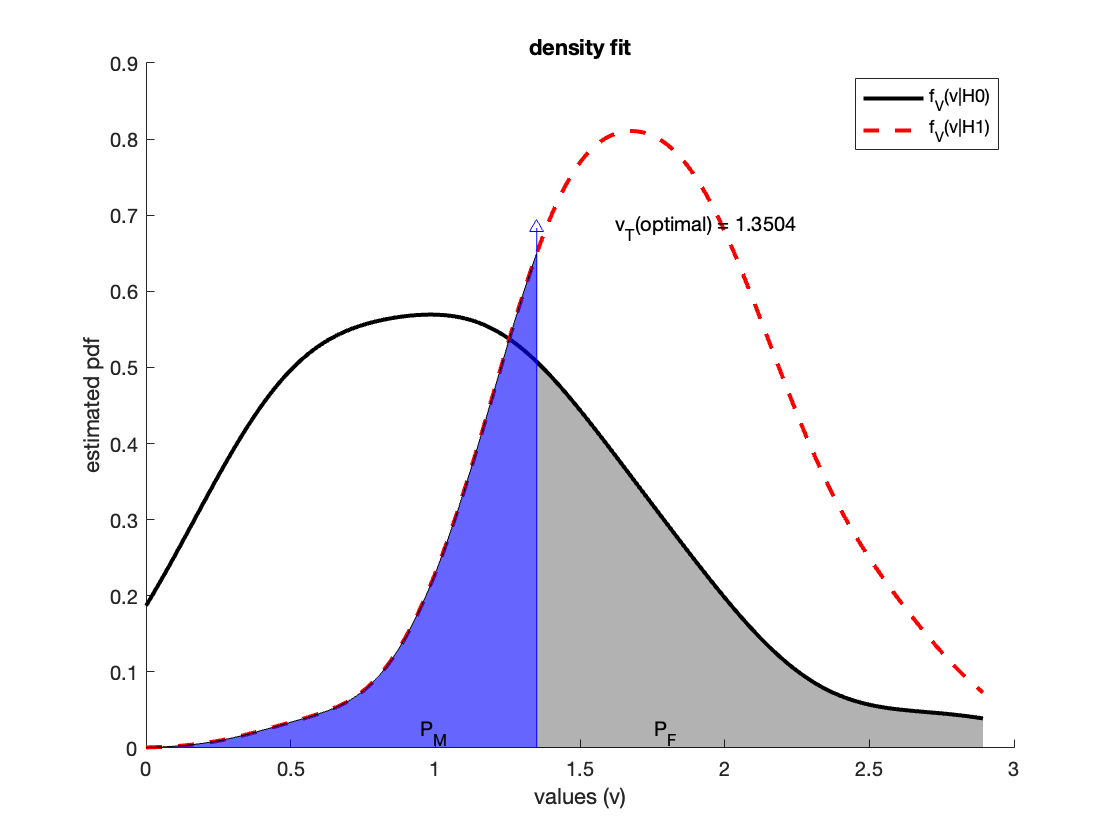


% Density fit
xi=0:.0001:max(Data);
[F_Absent]=ksdensity(Absent,xi,'Function','pdf' );
[F_Present]=ksdensity(Present,xi,'Function','pdf');

figure

vtOpt_n = 2.3679;
vtOpt_g = sorted_g(I_g);
vtOptLess = find(xi <= vtOpt);
vtOptInd = vtOptLess(end);
hold on
title("density fit")
xlabel("values (v)")
ylabel('estimated pdf')
plot(xi, F_Absent,'k-', 'LineWidth', 2) % Absent Black line
plot(xi, F_Present, 'r--', 'LineWidth', 2) % Present Red line
line([xi(vtOptInd) xi(vtOptInd)],[0 max(F_Absent)*1.2], 'Color', [0 0 1]) % Threshold line
plot(xi(vtOptInd),max(F_Absent)*1.2, 'b^') % blue triangle
area(xi(1:vtOptInd), F_Present(1:vtOptInd),'HandleVisibility','off', 'FaceColor' ,'b', 'FaceAlpha',0.6) % PM
area(xi(vtOptInd+1:end), F_Absent(vtOptInd+1:end),'HandleVisibility','off','facealpha',.3, 'FaceColor','k') % PF
legend("f_V(v|H0)", "f_V(v|H1)")
text(xi(vtOptInd)*0.7,0.02, 'P_M')
text(xi(vtOptInd)*1.3,0.02, 'P_F')
text(xi(vtOptInd)*1.2, max(F_Absent)*1.2, "v_T(optimal) = " + num2str(vtOpt))
hold off


% Calculations
fprintf("Optimal")

Optimal

 vtOpt = sorted(I)

vtOpt = 1.3504

 False_Alarm = sum(Absent > vtOpt == 1);
 False_Alarm_n = sum(Absent > vtOpt_n == 1);
 Miss_n = sum(Present > vtOpt_n == 0); 
 Miss = sum(Present > vtOpt == 0);
 confusion_matrix_optimal = [70-False_Alarm(1),False_Alarm(1);Miss(1),60 - Miss(1)]

confusion_matrix_optimal =     51    19
     9    51


  Tx_optimal = confusion_matrix_optimal' * [1/70, 0; 0, 1/60]

Tx_optimal =     0.7286    0.1500
    0.2714    0.8500


 confusion_matrix_intersection = [70-False_Alarm_n(1),False_Alarm_n(1);Miss_n(1),60 - Miss_n(1)];
  Tx_optimal_intersection = confusion_matrix_intersection' * [1/70, 0; 0, 1/60];
  
  fprintf("Midpoint")

Midpoint

  vtMid = 1.375

vtMid = 1.3750

  Error_rateMid = 0.2385

Error_rateMid = 0.2385

  PPV_mid = 0.7164

PPV_mid = 0.7164

  Confusion_matrix_mid = [51,12;19,48]

Confusion_matrix_mid =     51    12
    19    48


  transition_matrix_mid = [51/70, 1/5; 19/70,4/5]

transition_matrix_mid =     0.7286    0.2000
    0.2714    0.8000


  
  
  fprintf("Intersection")

Intersection

  vtInt = 1.25

vtInt = 1.2500

  Error_rateInt = 0.2462

Error_rateInt = 0.2462

  PPV_int = 0.6795

PPV_int = 0.6795

  Confusion_matrix_int = [45,7;25,53]

Confusion_matrix_int =     45     7
    25    53


  transiton_matrix_int = [9/14, 7/60; 5/14, 53/60]

transiton_matrix_int =     0.6429    0.1167
    0.3571    0.8833


function AOC=calculateROCarea(resp,dat)
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,dat,1);
AOC=AUC;
end
